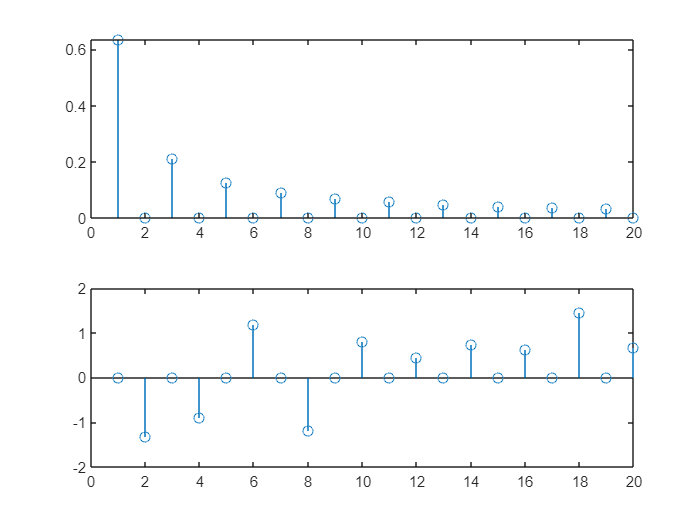


clc
close all
clear
t = 0:0.001:2;  
s = rectpuls(t - 1/2);  


T0 = 2;
f0 = 1 / T0;
w0=pi;
a0 = 0.5;
n = 1:20;  
An = zeros(size(n));
Bn = zeros(size(n));
A=zeros(size(n));
theta=zeros(size(n));
for k = n
    integrand_cos = @(t) rectpuls(t - 1/2) .* cos(k*w0*t);
    integrand_sin = @(t) rectpuls(t - 1/2) .* sin(k*w0*t);
    An(k) = (2/T0) * integral(integrand_cos, 0, T0);
    Bn(k) = (2/T0) * integral(integrand_sin, 0, T0);
    A(k)=(An(k)^2+Bn(k)^2)^0.5;%辅助角公式
    if Bn(k)<0
        A(k)=-A(k);
    end
    theta(k)=atan(An(k)/Bn(k));
end
figure;
subplot(2, 1, 1);
stem(n,A);
subplot(2,1,2);
stem(n,theta)

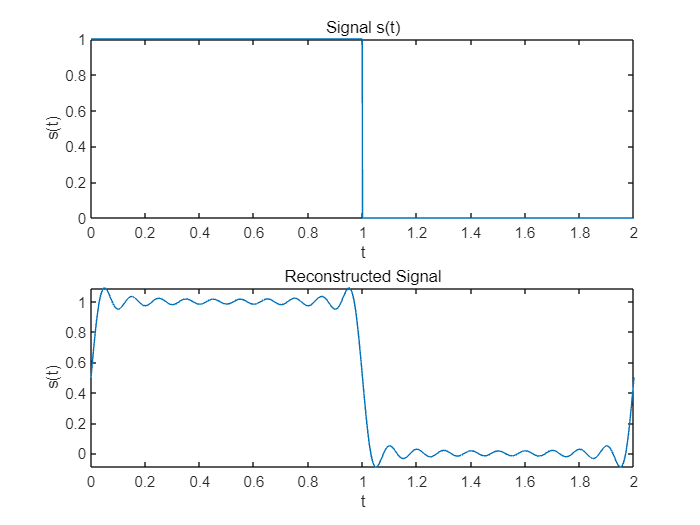


reconstructed = a0;
for k = n
     reconstructed = reconstructed + A(k)*sin(k*w0*t+theta(k));
end

figure;
subplot(2, 1, 1);
plot(t, s);
xlabel('t');
ylabel('s(t)');
title('Signal s(t)');

subplot(2, 1, 2);
plot(t, reconstructed);
xlabel('t');
ylabel('s(t)');
title('Reconstructed Signal');